% % connectivity values come from import values in CONN, you can find them in
% % set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 
% 
% addpath /Users/k.siudakrzywicka/Desktop/RDS_fMRI/RDS_localizers/scripts

% cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/color_rs_connectivity/behavioral_corelates

Error using cd
Cannot CD to /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/color_rs_connectivity/behavioral_corelates (Name is nonexistent or not a directory).

%f
% %locate subject numbers
% subs = dir('/Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/Processed_566_471_vol');
% subs = {subs.name};
% subs = cellfun(@str2double,subs(4:end));
% subs = subs-1000;
% subs = subs(1:end-6); %take out aditional 6 women
% 
% naming_categ = readtable('color_categorization_naming_2ndBlock.xlsx');
% partial = naming_categ{:, [2,3]}
% 
% behavior = naming_categ{:,7 };


Gender = categorical(partial(:,1));
Age = partial(:,2);

IVs = rmmissing(table(Gender, Age, behavior));
IVs.Age = zscore(IVs.Age);
IVs.RT = zscore(IVs.behavior);
IVs.behavior = [];
% connectivity values come from import values in CONN, you can find them in
% set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 

PCC_aMTG = [-0.0437327 0.204121 0.214168 0.144569 0.0979717 0.143297 0.256646 -0.0461484 0.137161 -0.32824 -0.059902 0.16525 0.134405 0.0968771 -0.0139668 NaN -0.0364638 0.0962955 0.148974 NaN]';
PCC_pMTG = [-0.102643 0.126645 0.303922 0.118971 0.184869 0.124062 0.249373 -0.0807016 0.269338 -0.281279 -0.0281272 -0.000114652 0.0118272 0.107977 -0.0376007 NaN -0.0250033 0.214788 0.170565 NaN]';
PCC_RDS = [0.0746116 0.132856 0.213245 0.111323 0.231646 0.148588 0.230983 0.131317 0.225872 -0.375882 -0.0863032 0.0881594 0.188548 0.129274 -0.133069 NaN -0.0739008 0.0586843 0.136695 NaN]';

VWFA_pMTG = [-0.0193152 0.056352 -0.0193091 -0.00963124 0.311898 0.161472 -0.0617169 0.083871 -0.0279307 0.00186289 -0.115217 0.112901 0.270371 -0.0376636 -0.208305 NaN 0.08725 -0.233355 0.0924544 NaN]';
VWFA_aMTG = [0.00985526 0.109287 -0.0956005 0.164656 0.291632 -0.0173411 0.00994892 0.182427 0.0536675 0.0166333 -0.124239 0.0269214 0.0977342 -0.0545523 -0.186126 NaN 0.0899484 -0.356432 0.0897821 NaN]';
VWFA_RDS = [0.0572547 0.0390671 -0.149659 0.357112 0.226607 0.0140029 0.0702111 0.0644431 0.0833635 -0.00426579 0.0224392 -0.0555433 0.146186 0.0337127 -0.10593 -0.108746 0.0664275 -0.31745 0.122595 0.180728]';

LOC_pMTG =[0.222693 -0.222871 0.28609 -0.0108748 -0.154032 0.141359 -0.0569973 -0.268134 0.332662 -0.036685 0.144858 -0.168866 -0.0667978 0.0918449 0.0154657 NaN 0.145194 -0.0753916 0.123785 NaN]';
LOC_aMTG =[0.276091 -0.051028 0.309615 0.15001 -0.200638 0.0130408 0.0426314 -0.17799 0.13429 0.0791903 0.130548 0.12685 -0.0910538 0.11019 -0.0764819 NaN 0.0911551 0.102333 0.171609 NaN]';
LOC_RDS = [0.341058 -0.106525 0.198604 0.00349724 -0.0180607 0.136061 -0.0230805 -0.126365 0.286579 0.0122656 -0.0275099 -0.0633376 -0.0168457 0.34915 -0.154373 0.112779 -0.00418837 0.135008 0.173876 -0.259432]';

connectivity = rmmissing(table(PCC_aMTG, PCC_pMTG, PCC_RDS, VWFA_pMTG, VWFA_aMTG, VWFA_RDS, LOC_pMTG, LOC_aMTG, LOC_RDS));
connectivity{:,:} = zscore(table2array(connectivity));
model_names = strcat(connectivity.Properties.VariableNames, '_model');



%calculate all models
for i = 1: width(connectivity)
    regressions(i).name = model_names{i};
    regressions(i).model = fitlm([IVs, connectivity(:,i)],[connectivity.Properties.VariableNames{i} ' ~ Gender+Age+RT']);
    regressions(i).partialR_RT = beta_to_partialR(regressions(i).model, 'RT');
    regressions(i).simple_model = step(regressions(i).model,'NSteps',10);
end

r = -0.5668

1. Adding Gender:RT, FStat = 4.7696, pValue = 0.047888


r = -0.5236

1. Removing Age, FStat = 0.015703, pValue = 0.90206
2. Removing Gender, FStat = 1.6767, pValue = 0.21494


r = -0.6559

1. Adding Gender:RT, FStat = 9.7742, pValue = 0.0080287
2. Removing Age, FStat = 2.3026, pValue = 0.15309


r = 0.2110

1. Removing Age, FStat = 0.021569, pValue = 0.88533
2. Removing Gender, FStat = 0.56131, pValue = 0.46532
3. Removing RT, FStat = 2.2627, pValue = 0.15201


r = 0.0757

1. Adding Age:RT, FStat = 8.182, pValue = 0.013387
2. Removing Gender, FStat = 1.2678, pValue = 0.28054


r = 0.0453

1. Adding Age:RT, FStat = 8.8451, pValue = 0.010762


r = -0.2055

1. Removing Gender, FStat = 0.010201, pValue = 0.92098
2. Removing Age, FStat = 0.11724, pValue = 0.73679
3. Removing RT, FStat = 0.73647, pValue = 0.40347


r = -0.0024

1. Removing RT, FStat = 7.7161e-05, pValue = 0.99312
2. Removing Age, FStat = 0.15353, pValue = 0.70069
3. Removing Gender, FStat = 0.019286, pValue = 0.89128


r = -0.2965

1. Removing Age, FStat = 0.1727, pValue = 0.68402
2. Removing Gender, FStat = 0.98817, pValue = 0.33596
3. Removing RT, FStat = 0.65866, pValue = 0.42894


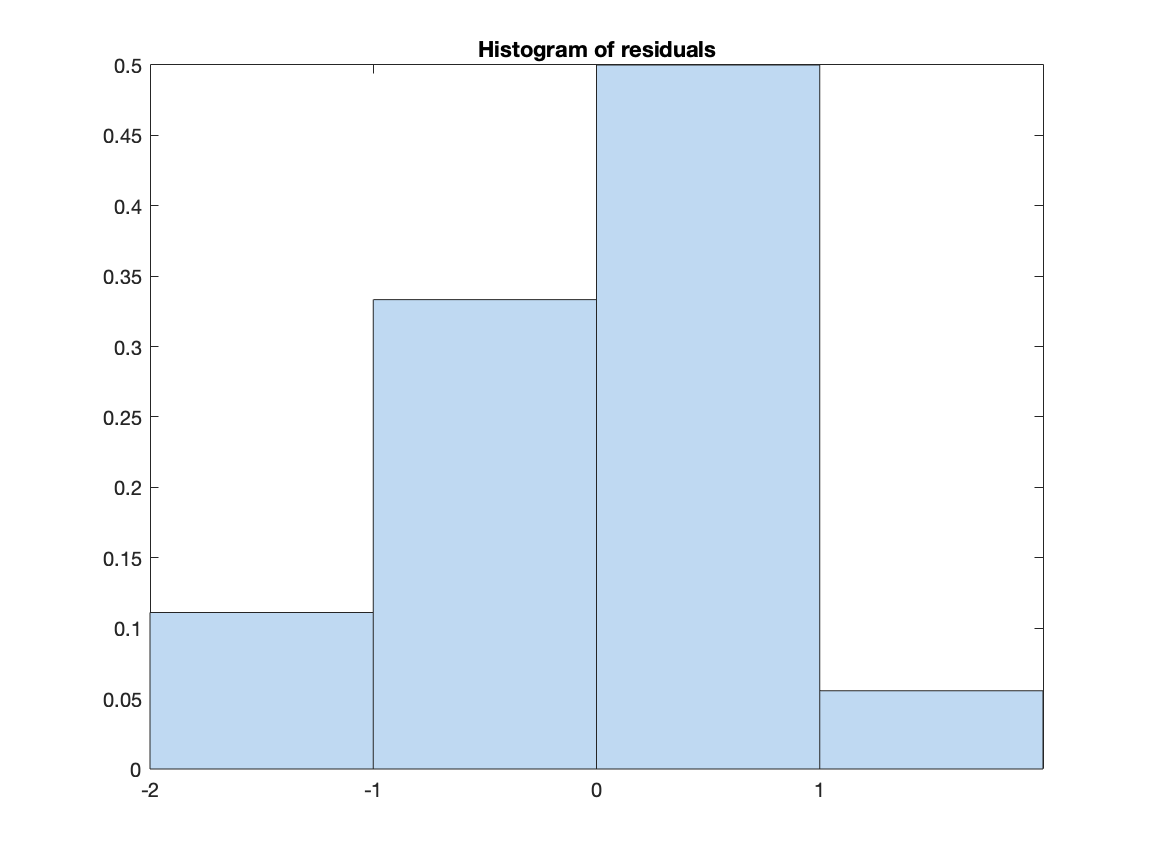

%figures and diagnostics for PCC - RDS connectivity

plotResiduals(regressions(3).model)

anova(regressions(3).model,  'summary')

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    _____    ________

    Total           17    17          1                     
    Model       7.5676     3     2.5225    3.744    0.036427
    Residual    9.4324    14    0.67375                     


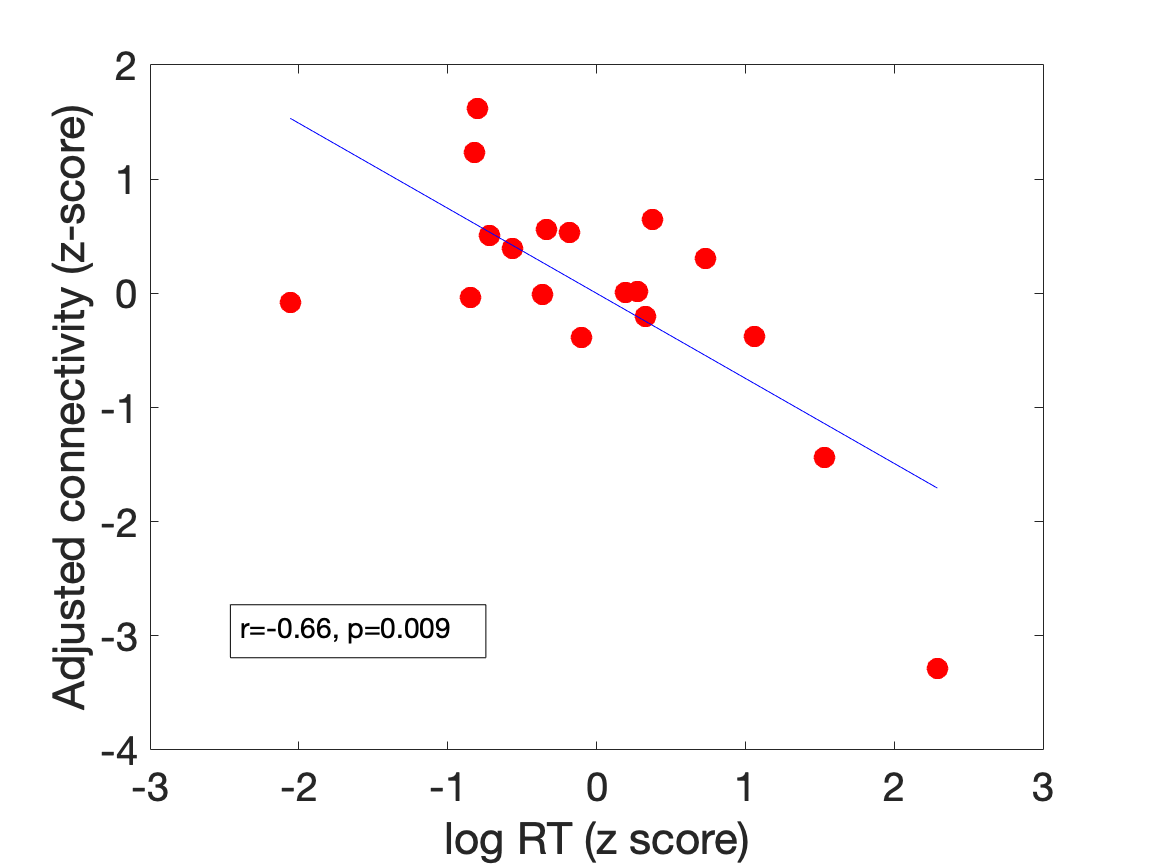

plotAdjustedResponse(regressions(3).model,'RT','markerfacecolor', 'r', 'MarkerEdgeColor', 'r', 'markersize', 10)
set(gca, 'FontSize', 20)
xlabel('log RT (z score)')
ylabel('Adjusted connectivity (z-score)')
title(' ')
s=findobj('type','legend');
delete(s)
a = annotation('textbox', [0.2 0 0.3 0.3], 'String', ...
    ['r=' num2str(round(regressions(3).partialR_RT,2))...
    ', p=' num2str(round(regressions(3).model.Coefficients.pValue(4),3))],...
    'FitBoxToText','on');
a.FontSize = 14;
set(gcf,'Units','inches','Position',[0 0 8 6])
plot2pdf('PC-RDS-c.naming.pdf')

%Run summary statistics for each of the models

for i = 1:9
    regressions(i).name
    anova(regressions(i).model,  'summary')
end

ans = 'PCC_aMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    ______    _______

    Total           17    17          1                     
    Model       5.7297     3     1.9099    2.3725    0.11421
    Residual     11.27    14    0.80502                     


ans = 'PCC_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    ______    _______

    Total           17    17          1                     
    Model        4.675     3     1.5583    1.7701    0.19895
    Residual    12.325    14    0.88035                     


ans = 'PCC_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    _____    ________

    Total           17    17          1                     
    Model       7.5676     3     2.5225    3.744    0.036427
    Residual    9.4324    14    0.67375                     


ans = 'VWFA_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model       2.6656     3    0.88852    0.86779    0.48087
    Residual    14.334    14     1.0239                      


ans = 'VWFA_aMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model       2.8271     3    0.94237    0.93087    0.45168
    Residual    14.173    14     1.0123                      


ans = 'VWFA_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue
                ______    __    _______    _______    ______

    Total           17    17          1                     
    Model       2.7498     3    0.91661    0.90052    0.4655
    Residual     14.25    14     1.0179                     


ans = 'LOC_pMTG_model'

ans = 3×5 table
                 SumSq     DF    MeanSq        F       pValue 
                _______    __    _______    _______    _______

    Total            17    17          1                      
    Model       0.88585     3    0.29528    0.25654    0.85542
    Residual     16.114    14      1.151                      


ans = 'LOC_aMTG_model'

ans = 3×5 table
                 SumSq     DF     MeanSq        F        pValue 
                _______    __    ________    ________    _______

    Total            17    17           1                       
    Model       0.19259     3    0.064198    0.053475    0.98303
    Residual     16.807    14      1.2005                       


ans = 'LOC_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model        1.868     3    0.62266    0.57608    0.64015
    Residual    15.132    14     1.0809                      



for i = 1:9
    regressions(i).name
    anova(regressions(i).simple_model,  'summary')
end

ans = 'PCC_aMTG_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          8.7548     4     2.1887    3.4509    0.039411
    . Linear       5.7297     3     1.9099    3.0113    0.068674
    . Nonlinear    3.0251     1     3.0251    4.7696    0.047888
    Residual       8.2452    13    0.63425                      


ans = 'PCC_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F      pValue 
                ______    __    _______    _____    _______

    Total           17    17          1                    
    Model        3.282     1      3.282    3.828    0.06809
    Residual    13.718    16    0.85737                    


ans = 'PCC_RDS_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue  
                   ______    __    _______    ______    _________

    Total              17    17          1                       
    Model          10.662     3      3.554    7.8506    0.0025809
    . Linear       7.5392     2     3.7696    8.3268     0.004145
    . Nonlinear    3.1228     1     3.1228    6.8981     0.019925
    Residual       6.3379    14    0.45271                       


ans = 'VWFA_pMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       4.3664e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'VWFA_aMTG_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          7.4534     3     2.4845    3.6435    0.039396
    . Linear       1.8732     2    0.93659    1.3735     0.28532
    . Nonlinear    5.5803     1     5.5803    8.1834    0.012582
    Residual       9.5466    14     0.6819                      


ans = 'VWFA_RDS_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          8.5198     4     2.1299    3.2651    0.046334
    . Linear       2.7498     3    0.91661    1.4051     0.28576
    . Nonlinear    5.7699     1     5.7699    8.8451    0.010762
    Residual       8.4802    13    0.65233                      


ans = 'LOC_pMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       1.1631e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'LOC_aMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       3.2108e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'LOC_RDS_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       8.4592e-33     0    Inf       Inf    NaN   
    Residual            17    17      1                    


reg_pMTG = rmmissing(table(Gender, Age, behavior, connectivity(:,2), 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'}));
reg_pMTG_model = fitlm(reg_pMTG,'Connectivity~Gender+Age+RT')

reg_pMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE         tStat       pValue 
                   _________    _________    ________    ________

    (Intercept)      0.10555      0.44239     0.23859     0.81488
    Gender_2         -0.1125      0.14116    -0.79693      0.4388
    Age            0.0010423    0.0083174     0.12531     0.90206
    RT              -0.57949      0.25234     -2.2965    0.037601


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.143
R-squared: 0.275,  Adjusted R-Squared 0.12
F-statistic vs. constant model: 1.77, p-value = 0.199

%h2 = plotAdjustedResponse(reg_pMTG_model,'RT')
% model on Z scores of non-binary vars

reg_pMTG_Z = [reg_pMTG(:,1), array2table(zscore(reg_pMTG{:,2:end}),'VariableNames', {'Age', 'RT', 'Connectivity'})];
reg_pMTG_Z_model = fitlm(reg_pMTG_Z,'Connectivity~Gender+Age+RT')

reg_pMTG_Z_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate      SE        tStat       pValue 
                   ________    _______    ________    ________

    (Intercept)     0.16399    0.30208     0.54287     0.59576
    Gender_2       -0.73795      0.926    -0.79693      0.4388
    Age            0.047325    0.37765     0.12531     0.90206
    RT             -0.64843    0.28236     -2.2965    0.037601


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.938
R-squared: 0.275,  Adjusted R-Squared 0.12
F-statistic vs. constant model: 1.77, p-value = 0.199

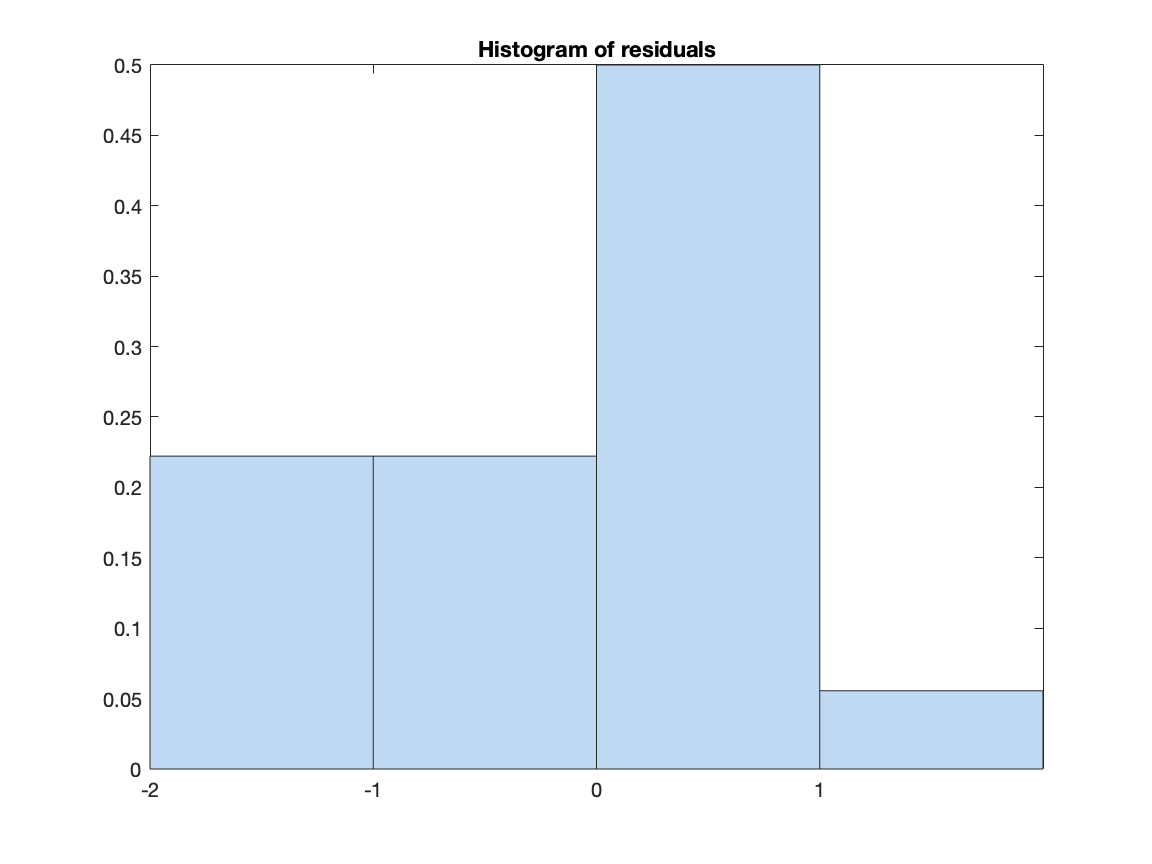

plotResiduals(reg_pMTG_Z_model)



reg_pMTG_Z_model_simple = step(reg_pMTG_Z_model,'NSteps',10)

1. Removing Age, FStat = 0.015703, pValue = 0.90206
2. Removing Gender, FStat = 1.6767, pValue = 0.21494


reg_pMTG_Z_model_simple = Linear regression model:
    Connectivity ~ 1 + RT

Estimated Coefficients:
                    Estimate       SE          tStat       pValue 
                   __________    _______    ___________    _______

    (Intercept)    -2.587e-17    0.21825    -1.1854e-16          1
    RT               -0.43939    0.22457        -1.9565    0.06809


Number of observations: 18, Error degrees of freedom: 16
Root Mean Squared Error: 0.926
R-squared: 0.193,  Adjusted R-Squared 0.143
F-statistic vs. constant model: 3.83, p-value = 0.0681

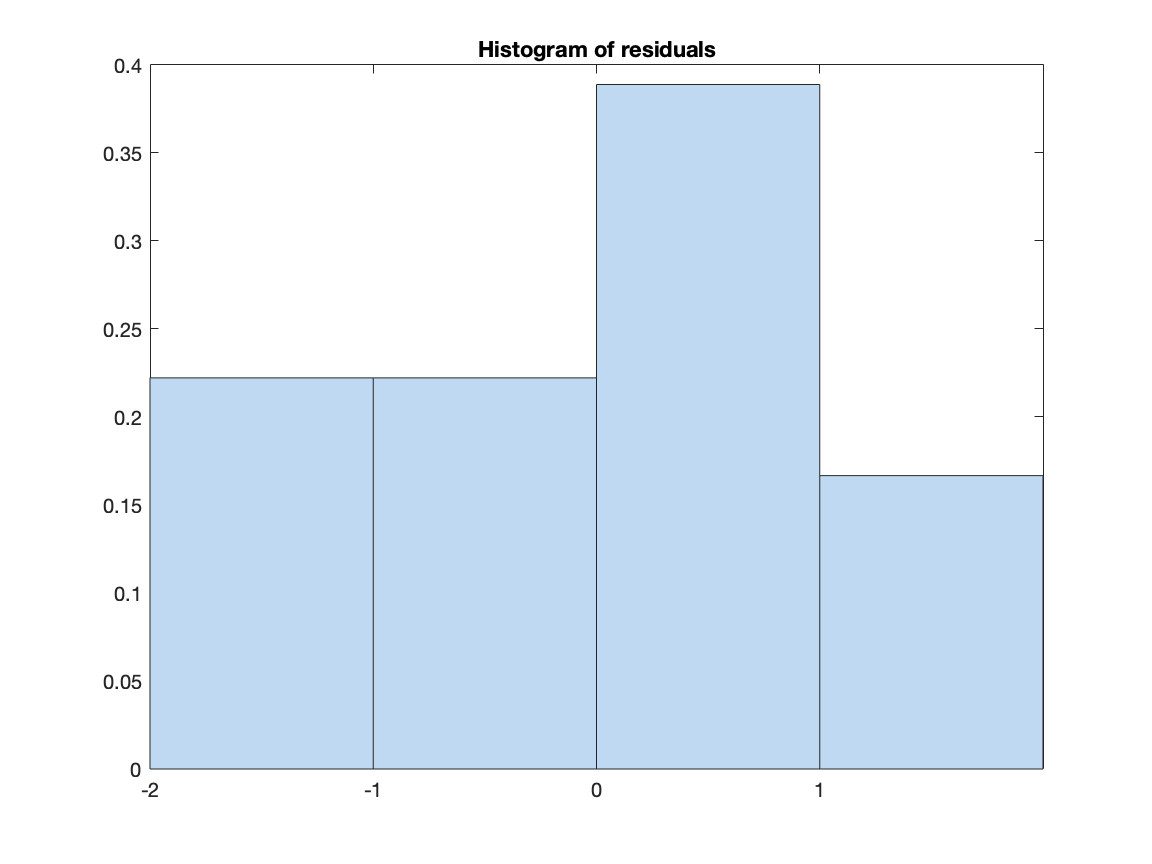

plotResiduals(reg_pMTG_Z_model_simple)



%beta_to_partialR(reg_pMTG_Z_model_simple, 'RT');

ROI rom RDS's analysis

PCC_RDS_ROI_conn = [0.0746116 0.132856 0.213245 0.111323 0.231646 0.148588 0.230983 0.131317 0.225872 -0.375882 -0.0863032 0.0881594 0.188548 0.129274 -0.133069 NaN -0.0739008 0.0586843 0.136695 NaN];
PCC_RDS_ROI = rmmissing(table(Gender, Age, behavior, PCC_RDS_ROI_conn', 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'}));

PCC_RDS_ROI_model = fitlm(PCC_RDS_ROI,'Connectivity~Gender+Age+RT')

PCC_RDS_ROI_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)      0.12699      0.39831    0.31882      0.75457
    Gender_2        -0.24578       0.1271    -1.9337     0.073622
    Age            0.0015354    0.0074887    0.20503       0.8405
    RT              -0.68518       0.2272    -3.0158    0.0092569


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.129
R-squared: 0.445,  Adjusted R-Squared 0.326
F-statistic vs. constant model: 3.74, p-value = 0.0364

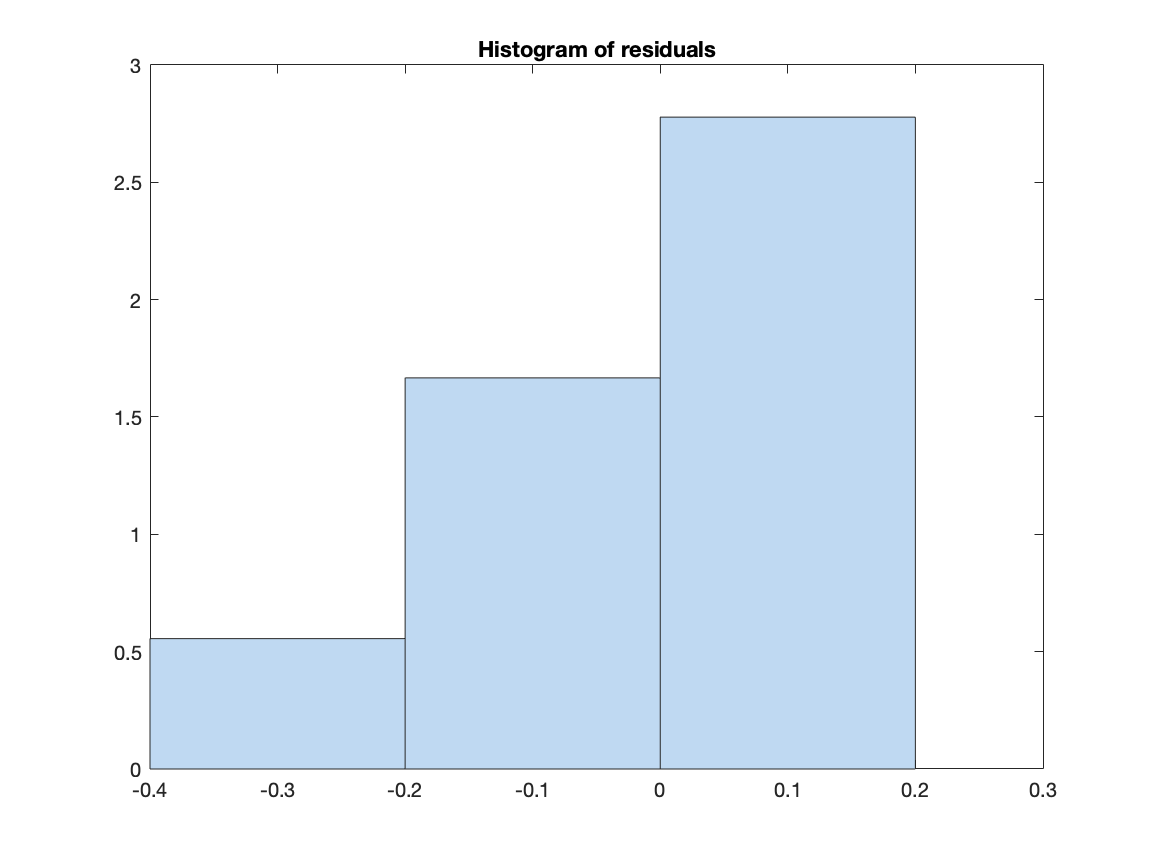

plotResiduals(PCC_RDS_ROI_model)


% h3 = plotAdjustedResponse(PCC_RDS_ROI_model,'RT', 'markerfacecolor', 'r', 'MarkerEdgeColor', 'r', 'markersize', 10)
% set(gca, 'FontSize', 20)
% xlabel('logRT')
% title(' ')
% % s=findobj('type','legend');
% % delete(s)
% set(gcf,'Units','inches','Position',[0 0 8 6])

% PCC_RDS_ROI_model_simple = step(PCC_RDS_ROI_model,'NSteps',10)
% plotResiduals(PCC_RDS_ROI_model_simple)
% plotInteraction(PCC_RDS_ROI_model_simple,'RT','Gender')
% plotAdjustedResponse(PCC_RDS_ROI_model_simple, 'RT')

model on z-scores

PCC_RDS_ROI_Z = [PCC_RDS_ROI(:,1), array2table(zscore(PCC_RDS_ROI{:,2:end}),'VariableNames', {'Age', 'RT', 'Connectivity'})];


PCC_RDS_ROI_Z_model = fitlm(PCC_RDS_ROI_Z,'Connectivity~Gender+Age+RT')

PCC_RDS_ROI_Z_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)     0.34811    0.26427     1.3173       0.2089
    Gender_2        -1.5665    0.81008    -1.9337     0.073622
    Age            0.067738    0.33038    0.20503       0.8405
    RT             -0.74495    0.24701    -3.0158    0.0092569


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.821
R-squared: 0.445,  Adjusted R-Squared 0.326
F-statistic vs. constant model: 3.74, p-value = 0.0364

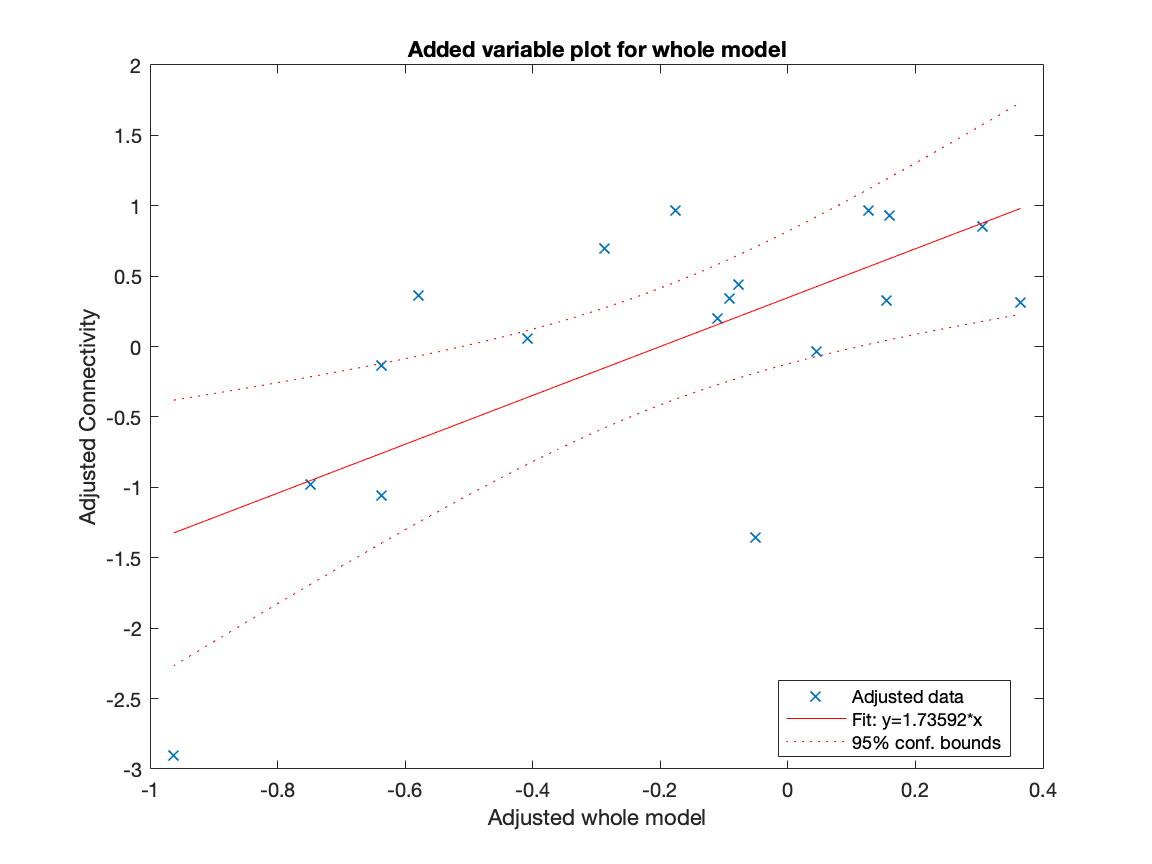

plot(PCC_RDS_ROI_Z_model)


plotResiduals(PCC_RDS_ROI_Z_model)

h4 = plotAdjustedResponse(PCC_RDS_ROI_Z_model,'RT','markerfacecolor', 'r', 'MarkerEdgeColor', 'r', 'markersize', 10)

h4 =   2×1 Line array:

  Line    (data)
  Line    (fit)


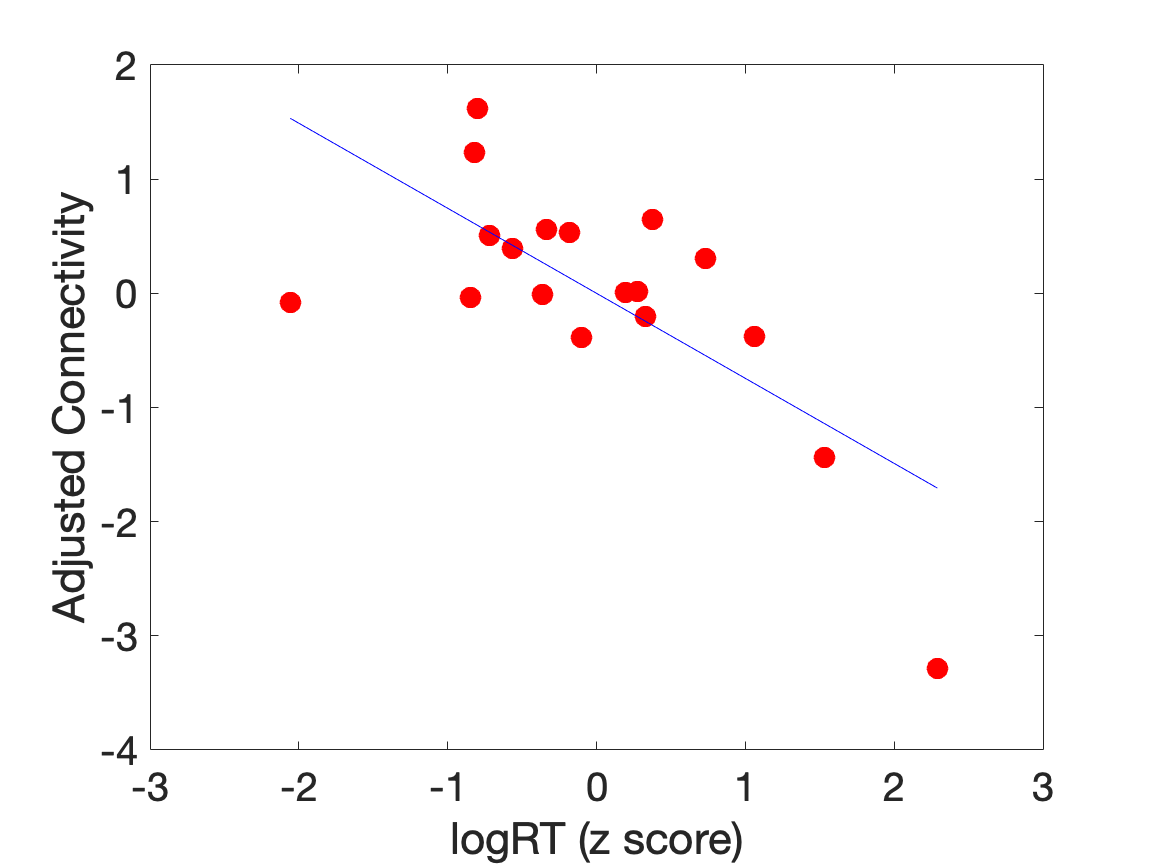

set(gca, 'FontSize', 20)
xlabel('logRT (z score)')
title(' ')
s=findobj('type','legend');
delete(s)

set(gcf,'Units','inches','Position',[0 0 8 6])
beta_to_partialR(PCC_RDS_ROI_Z_model, 'RT');

r = -0.6559




PCC_RDS_ROI_Z_model_simple = step(PCC_RDS_ROI_model,'NSteps',10)

1. Adding Gender:RT, FStat = 9.7742, pValue = 0.0080287
2. Removing Age, FStat = 2.3026, pValue = 0.15309


PCC_RDS_ROI_Z_model_simple = Linear regression model:
    Connectivity ~ 1 + Gender*RT

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.23592    0.041505     5.6841    5.6412e-05
    Gender_2       -0.18981    0.078959    -2.4039      0.030637
    RT             -0.86014     0.19722    -4.3612    0.00065173
    Gender_2:RT      1.4853     0.56552     2.6264      0.019925


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.106
R-squared: 0.627,  Adjusted R-Squared 0.547
F-statistic vs. constant model: 7.85, p-value = 0.00258

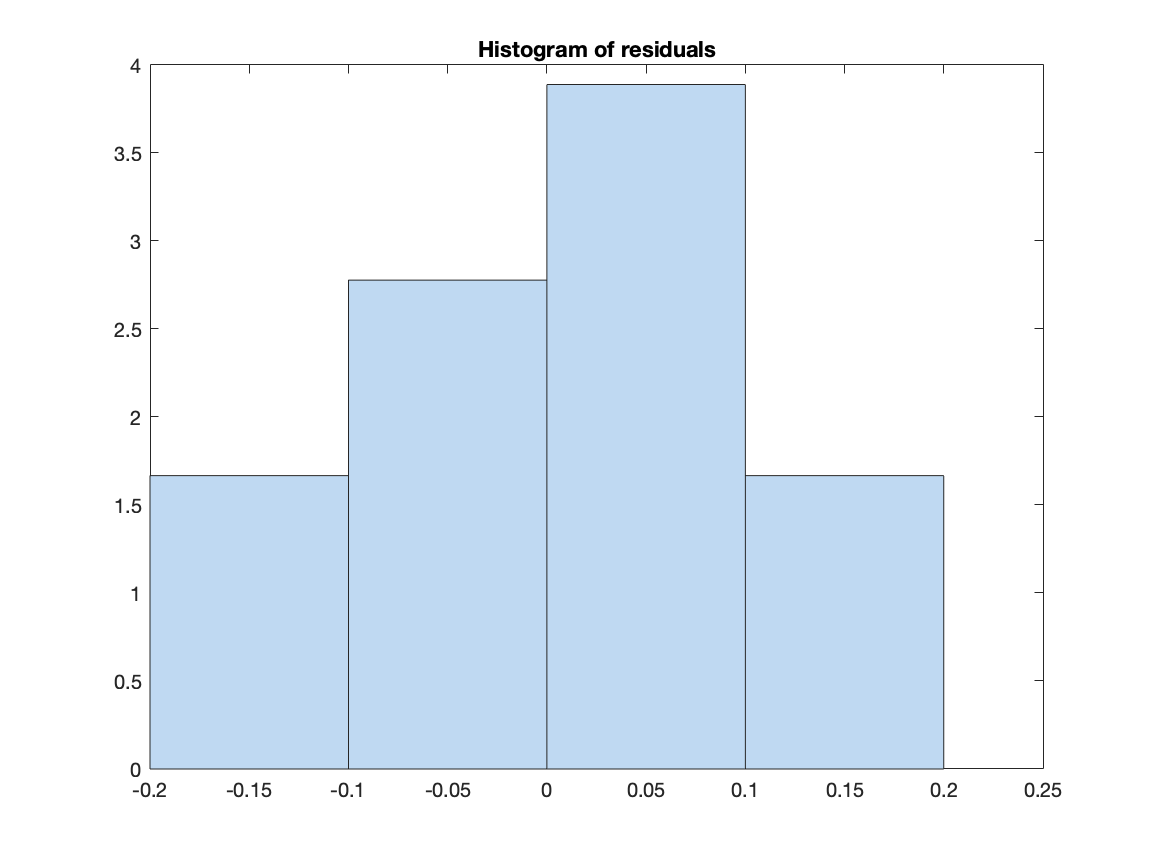

plotResiduals(PCC_RDS_ROI_Z_model_simple)

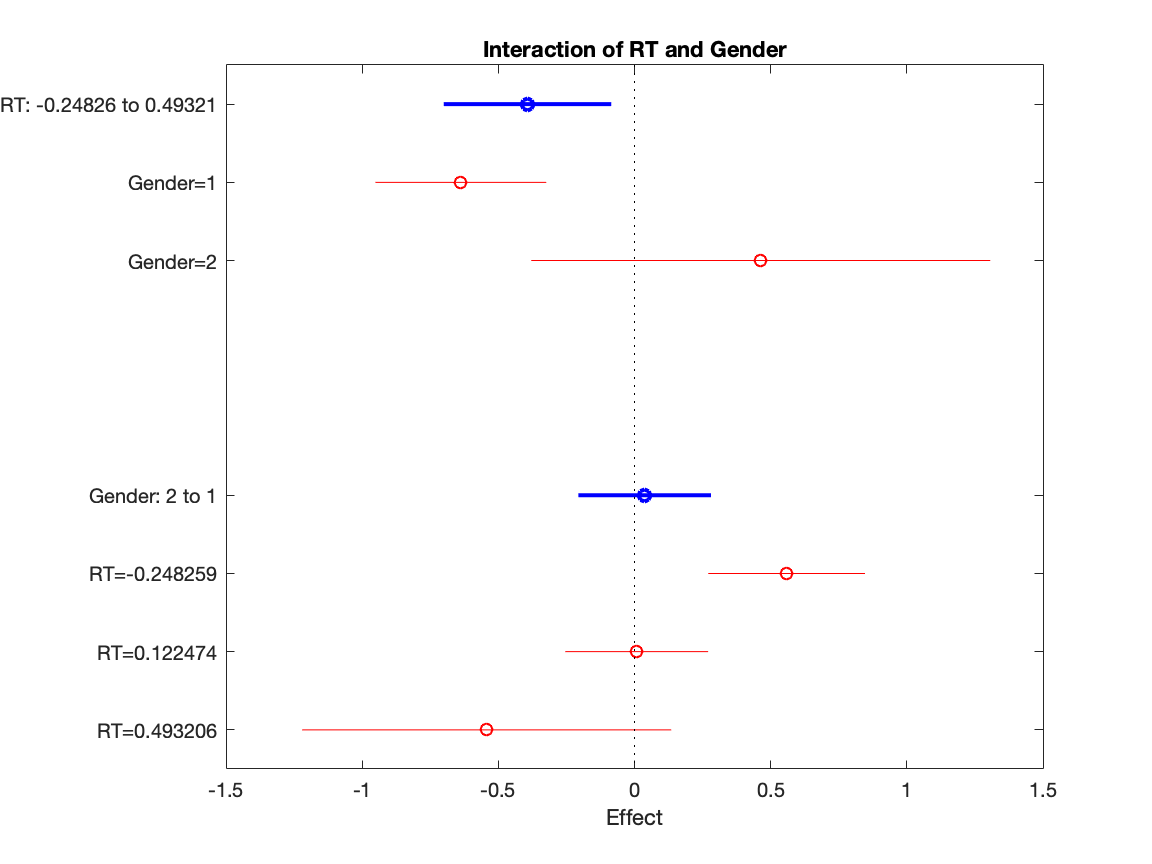

plotInteraction(PCC_RDS_ROI_Z_model_simple,'RT','Gender')

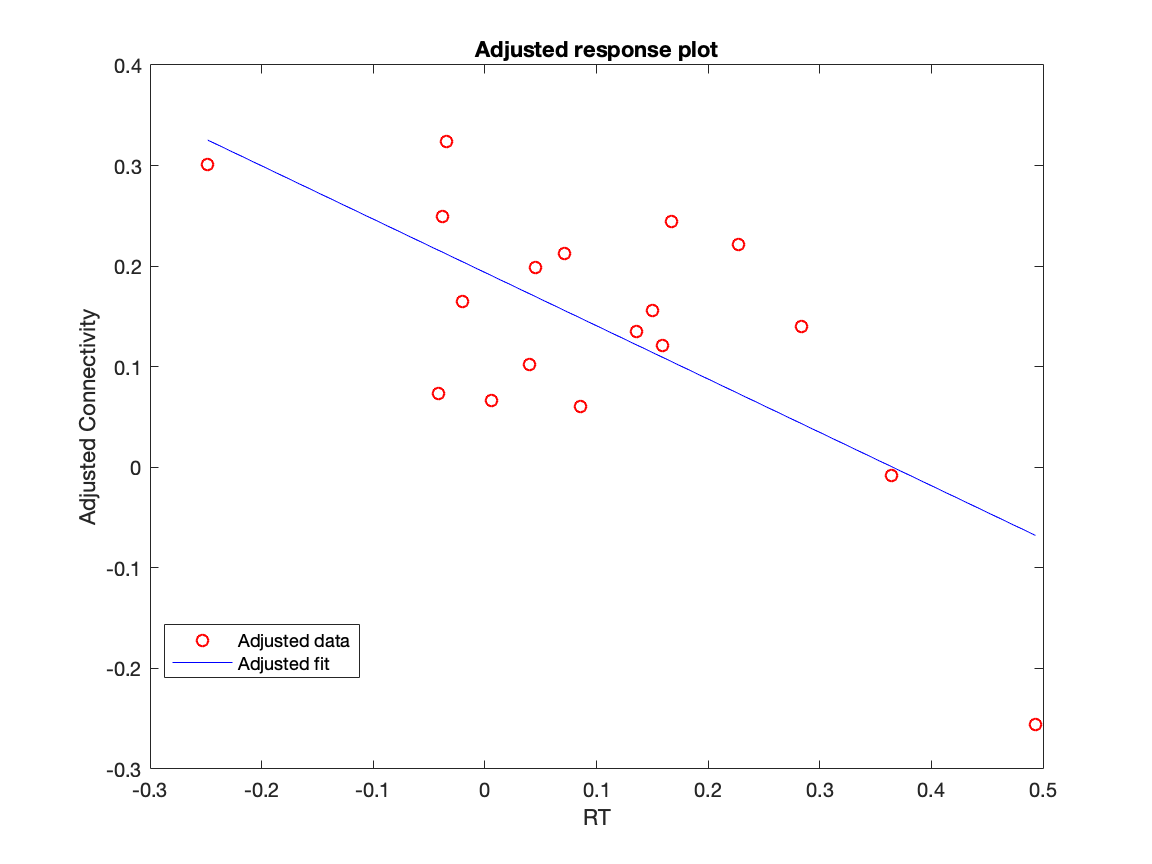

plotAdjustedResponse(PCC_RDS_ROI_Z_model_simple, 'RT')

recalculate beta to partial correlation coefficient

beta_to_partialR(PCC_RDS_ROI_Z_model_simple, 'RT');

r =    -5.2816
    9.1204


Similar analysis for specificity (is it only PCC or othe domain region also show this connectivity pattern?)

VWFA_pMTG_conn = [-0.0193152 0.056352 -0.0193091 -0.00963124 0.311898 0.161472 -0.0617169 0.083871 -0.0279307 0.00186289 -0.115217 0.112901 0.270371 -0.0376636 -0.208305 NaN 0.08725 -0.233355 0.0924544 NaN]

VWFA_pMTG_conn =    -0.0193    0.0564   -0.0193   -0.0096    0.3119    0.1615   -0.0617    0.0839   -0.0279    0.0019   -0.1152    0.1129    0.2704   -0.0377   -0.2083       NaN    0.0872   -0.2334    0.0925       NaN


VWFA_pMTG = rmmissing(table(Gender,Age, behavior, VWFA_pMTG_conn'));
VWFA_pMTG = [VWFA_pMTG.Gender, zscore(VWFA_pMTG(:,2:end))];

Error using sum
Invalid data type. First argument must be numeric or logical.

Error in mean (line 117)
        y = sum(x, dim, flag)/size(x,dim);

Error in zscore (line 43)
mu = mean(x,dim);

% VWFA_pMTG = array2table([partial,behavior,VWFA_pMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
% VWFA_pMTG_model = fitlm(VWFA_pMTG,'Connectivity~Gender+Age+RT')
% step(VWFA_pMTG_model,'NSteps',10)




VWFA_aMTG = [0.00985526 0.109287 -0.0956005 0.164656 0.291632 -0.0173411 0.00994892 0.182427 0.0536675 0.0166333 -0.124239 0.0269214 0.0977342 -0.0545523 -0.186126 NaN 0.0899484 -0.356432 0.0897821 NaN]

VWFA_aMTG = array2table([partial,behavior,VWFA_aMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
VWFA_aMTG_model = fitlm(VWFA_aMTG,'Connectivity~Gender+Age+RT')


VWFA_RDS = [0.0572547 0.0390671 -0.149659 0.357112 0.226607 0.0140029 0.0702111 0.0644431 0.0833635 -0.00426579 0.0224392 -0.0555433 0.146186 0.0337127 -0.10593 -0.108746 0.0664275 -0.31745 0.122595 0.180728]
VWFA_RDS = array2table([partial,behavior,VWFA_RDS'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
VWFA_RDS_model = fitlm(VWFA_RDS,'Connectivity~Gender+Age+RT')




LOC_pMTG =[0.222693 -0.222871 0.28609 -0.0108748 -0.154032 0.141359 -0.0569973 -0.268134 0.332662 -0.036685 0.144858 -0.168866 -0.0667978 0.0918449 0.0154657 NaN 0.145194 -0.0753916 0.123785 NaN]
LOC_pMTG = array2table([partial,behavior,LOC_pMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
LOC_pMTG_model = fitlm(LOC_pMTG,'Connectivity~Gender+Age+RT')




LOC_aMTG =[0.276091 -0.051028 0.309615 0.15001 -0.200638 0.0130408 0.0426314 -0.17799 0.13429 0.0791903 0.130548 0.12685 -0.0910538 0.11019 -0.0764819 NaN 0.0911551 0.102333 0.171609 NaN]

LOC_aMTG = array2table([partial,behavior,LOC_aMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
LOC_aMTG_model = fitlm(LOC_aMTG,'Connectivity~Gender+Age+RT')
LOC_RDS = [0.341058 -0.106525 0.198604 0.00349724 -0.0180607 0.136061 -0.0230805 -0.126365 0.286579 0.0122656 -0.0275099 -0.0633376 -0.0168457 0.34915 -0.154373 0.112779 -0.00418837 0.135008 0.173876 -0.259432];
LOC_RDS = array2table([partial,behavior,LOC_RDS'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
LOC_RDS = fitlm(LOC_RDS,'Connectivity~Gender+Age+RT')

check the variance in the left MTG cluster

lMTG_cluster = [-0.0333257 0.0415116 0.0251545 0.0814467 0.00731221 0.00183926 0.0398293 -0.0403542 0.033536 -0.381939 -0.226757 -0.059801 0.000424696 0.118078 0.0859184 NaN -0.100834 -0.068798 -0.0223617 NaN]

UnivarScatter(rmmissing(lMTG_cluster)')

check the variance in RDS cluster:

UnivarScatter(rmmissing(PCC_RDS_ROI.Connectivity))